# RoadRunnerとMATLABの接続

## 変数、RoadRunnerをクリーンアップ

if exist("rrApp", "var")
    if class(rrApp) == "roadrunner"
        rrApp.close();
    end
end
if exist("rrSim", "var")
    delete(rrSim);
end
close all;
clear;

## RoadRunnerをMATLABから起動する

RoadRunnerをinstallしているフォルダ、プロジェクトフォルダを選択してOK

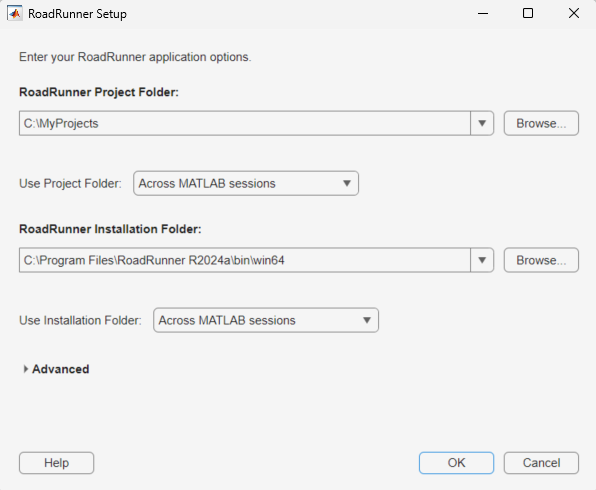

rrApp = roadrunnerSetup(); %R2023bより可能
rrApp

rrApp =   roadrunner with properties:

    InstallationFolder: 'C:\Program Files\RoadRunner R2024b\bin\win64'
               Version: "R2024b Update 3 (1.9.3.059d0255441)"
             NoDisplay: 0


## RoadRunnerを閉じる

rrApp.close();

## 先ほどGUIウィンドウで開いたプロジェクトを再度開く

rrApp = roadrunner(); % roadrunnerSetup()のGUIウインドウで開いたインストール先、プロジェクトが自動で指定される
% 下記のようにプロジェクトフォルダとインストールフォルダを明示的に指定することも可能
% 例題ではよくこの形式で作成されているため、例題実行時はご自身のパスに書き換えるようお願いします
% rrProj = "C:\RR\MyProject";
% rrApp = roadrunner(rrProj,InstallationFolder="C:\Program Files\RoadRunner R2024a\bin\win64");

## MATLAB関数よりシーン/シナリオを開く

**シーンを開く**

<ProjectFolder>/Scenes/ にある<SceneName>.rrsceneを開くことが可能

rrApp.openScene("ScenarioBasic"); %<ProjectFolder>/Scenes/ScenarioBasic.rrscene を開く

**シナリオを開く**

<ProjectFolder>/Scenarios にある<ScenarioName>.rrscenarioを開くことが可能

rrApp.openScenario("TrajectoryCutIn"); %<ProjectFolder>/Scenarios/TrajectoryCutIn.rrscenarioを開く

**シナリオを実行する**

下記の関数でシナリオを実行

rrSim = rrApp.createSimulation();
set(rrSim,"Logging","on");

% Simulationを開始する
set(rrSim,"SimulationCommand","Start");
% RoadRunner ScenarioのSimulation実行が終了するまで待機
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end

## 発展：RoadRunnerの実行Logを取得する

各車両の走行軌跡や速度データを取得可能

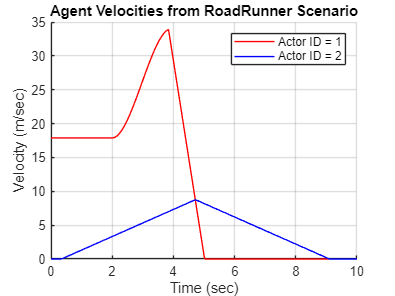

% logを取得する設定をONにする
set(rrSim,"Logging","on");

% シミュレーション実行
set(rrSim,"SimulationCommand","Start");
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end

% logを取得
rrLog = get(rrSim,"SimulationLog");

% 車両の速度を取得
velocityAgent1 = get(rrLog,'Velocity','ActorID',1); % Actor1の速度取得
velocityAgent2 = get(rrLog,'Velocity','ActorID',2); % Actor2の速度取得
time = [velocityAgent1.Time];% Actor1の時刻取得

% 車両の速度をプロット
helperPlotVelocity(time, velocityAgent1, velocityAgent2);

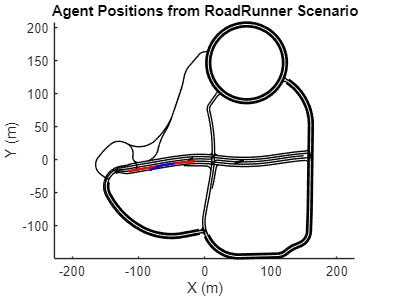


% 車両の軌跡と地図をプロット
helperPlotTrajectoryMap(rrSim, rrLog);

## 参考

**シナリオを実行する (R2024a以降)**

% rrApp.simulateScenario("IsBlocking", true); % R2024a以降実行可能

function helperPlotVelocity(time, velocityAgent1, velocityAgent2)
    velMagAgent1 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent1);
    velMagAgent2 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent2);

    % Plot the agent velocities with respect to simulation time using the plot function. Label the graph and the x and y axes.
    figure
    hold on
    plot(time,velMagAgent1,"r")
    plot(time,velMagAgent2,"b")
    grid on
    title("Agent Velocities from RoadRunner Scenario")
    ylabel("Velocity (m/sec)")
    xlabel("Time (sec)")
    legend("Actor ID = 1","Actor ID = 2")
end
function helperPlotTrajectoryMap(rrSim, rrLog)
    hdMap = get(rrSim, "Map");
    lanes = hdMap.Lanes;
    % Loop through each of the lane specifications using a for loop and plot the lane coordinates.
    
    figure
    hold on
    for i = 1:numel(lanes)
        control_points = lanes(i).Geometry;
        x_coordinates = control_points(:,1);
        y_coordinates = control_points(:,2);
        plot(x_coordinates, y_coordinates, 'black');
    end
    axis equal
    
    
    % Extract the positions of the vehicles and plot them on the lanes.
    poseActor1 = rrLog.get('Pose','ActorID',1);
    positionActor1_x = arrayfun(@(x) x.Pose(1,4),poseActor1);
    positionActor1_y = arrayfun(@(x) x.Pose(2,4),poseActor1);
    plot(positionActor1_x,positionActor1_y,"r","LineWidth",2)
    
    poseActor2 = rrLog.get('Pose','ActorID',2);
    positionActor2_x = arrayfun(@(x) x.Pose(1,4),poseActor2);
    positionActor2_y = arrayfun(@(x) x.Pose(2,4),poseActor2);
    plot(positionActor2_x,positionActor2_y,"b","LineWidth",2)
    
    title("Agent Positions from RoadRunner Scenario")
    ylabel("Y (m)")
    xlabel("X (m)")
end